# Explore the dynamics of a 1-dof Spring Mass Damper

In this example we're going to derive and then implement the equations of motion for 1-dof Spring Mass Damper system. Specifically we're going to derive the equations of motion using's ***Lagrange's method***.  The system that we're going to explore is shown below.

#  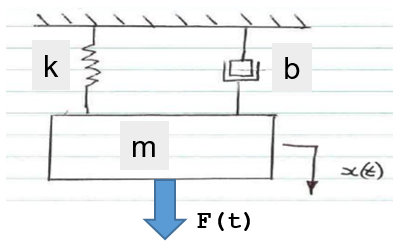

## Background:

From our year 1 class in physics and mechanics, we derived using ***Newton's 2nd law***, the equation of motion for the dynamics of a Spring Mass damper system.  Recall that it had the following form:


$$m\ldotp \ddot{x} \text{ }\text{ }+\text{ }\text{ }b\ldotp \dot{x} \text{ }\text{ }+\text{ }\text{ }k\ldotp x=F\left(t\right)$$


Today we'll use the ***Lagrangian approach*** to derive the same equations of motion for our spring mass damper.  We're going to break this problem down into the following 6 steps:

- Define Model Parameters

- Apply the governing physics

- Apply Lagrange's equation

- Isolate our expression for $\ddot{x} \text{ }\left(t\right)$

- Convert our Analytical expression for $\ddot{x} \text{ }\text{ }$into a Simulink block

- Simulate of model of this dynamic system

## Euler-Lagrange equations:

Recall our earlier class where we derived and summarised the fundamental Lagrangian equations that allow us to derive system equations of motion:

      $\frac{d}{dt}\frac{\partial L}{\partial \dot{q}_k} - \frac{\partial L}{\partial q_k} = Q_k $        where         $Q_k = 
\sum_{i=1}^{Nf_{nc}}
\pmatrix{
\vec{F_i} \thinspace . \thinspace \frac{\partial \vec{v \thinspace _i}}{\partial \dot{q \thinspace}_k}
}  \enspace + \enspace
\sum_{j=1}^{N\tau_{nc}}
\pmatrix{
\vec {\tau_j} \thinspace . \thinspace \frac{\partial \vec{\omega \thinspace _j}}{\partial \dot{q \thinspace}_k}
}
$

where:

- L       :    is the system Lagrangian, ie:  L = KE - PE

- $q_k$     :    is  the $k^{th}$ generalised co-ordinate 

- $Q_k$     :    is the generalised force associated with the $k^{th}$ generalised co-ordinate $q_k$

- $Nf_{nc}$  :    is the number of active NON conservative forces

- $N\tau_{nc}$ :    is the number of active NON conservative TORQUES

- $\vec{v_i}$      :    is the velocity vector of the point associated with the applied force.

- $\vec{\omega_i}$     :    is the angular velocity about the point associated with the applied torque. 

`Bradley Horton : 13-Sep-2016, bradley.horton@mathworks.com.au`           

# STEP_1:  Define Model parameters

 Define some Symbolic variables that parameterise our model:

syms  m  k  b  F

And here are some variables associatd with our $x\left(t\right)$, $\dot{x} \left(t\right)$ and $\ddot{x} \left(t\right)$

syms          t       x(t) 
syms              THE_X    THE_XD         THE_XDD
HOLDER_list = [   THE_X,   THE_XD,        THE_XDD];
actual_list = [    x(t),   diff(x(t),t),  diff(x(t),t,2)];

# STEP_2:  Apply the governing physics  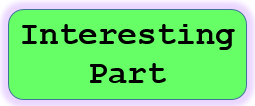

v  = diff(x,t);     % velocity
KE = 0.5*m*v(t)^2;  % KINETIC energy
PE = 0.5*k*x(t)^2;  % POTENTIAL energy
L  = KE - PE        % our Lagrangian

$$L = \frac{m\,{\left(\frac{\partial }{\partial t}x\left(t\right)\right)}^{2}}{2}-\frac{k\,{x\left(t\right)}^{2}}{2}$$

# **ATTENTION:**  you have a new friend, its name is `diff()`

When it comes to applying the [*Chain Rule of differentiation*](https://en.wikipedia.org/wiki/Chain_rule) - ***CONGRATULATIONS*** you've already earnt your merit badge in 1st year maths.  SO I know .... that YOU know .... how to do things like this:

syms z(t) y(t)
g     = (sin(z)).^2

$$g(t) = {\sin\left(z\left(t\right)\right)}^{2}$$

So what's $\frac{\mathit{\text{d}}g}{\mathit{\text{dt}}}$

dg_dt = diff(g,t)    % <------ YOU can do this !

$$dg\_dt(t) = 2\,\cos\left(z\left(t\right)\right)\,\sin\left(z\left(t\right)\right)\,\frac{\partial }{\partial t}z\left(t\right)$$

In this course we'll spend ALOT of time constructing expressions that contain DOZENS, sometimes HUNDREDS or even THOUSANDS of terms.  For example, expressions that look like this:

f = bh_some_ct_example_func(y, z, t);

So if we need to compute things like $\frac{\mathit{df}}{\mathit{dt}}$, let's allow MATLAB to do in 1 microsecond what could take you minutes/hours to do by hand, eg:

df_dt = diff(f,t);

So `diff()`  - it computes the analytical derivative of a symbolic function.  You can read more about it in MATLAB's help browser:

% doc symbolic differentiation

 We'll be using it alot, so let's start practicing with it now !

# STEP_3:  Apply Lagrange's equation - PART 1 of 3  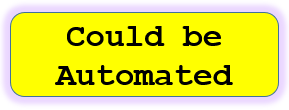

Now let's start applying Lagranges equation $\frac{d}{dt}\frac{\partial L}{\partial \dot{x}} - \frac{\partial L}{\partial x} $ :

                   % OLD_LIST       NEW_LIST
L_new   = subs(L, actual_list,   HOLDER_list);

  Our 1st piece is:  $ \frac{\partial L}{\partial x} $        

dLdx    = diff(L_new, THE_X);

 Our 2nd piece is: $\frac{\partial L}{\partial \dot{x}} $

dLdxdot =  diff(L_new, THE_XD);

 Our 3rd piece is: $\frac{d}{dt}\frac{\partial L}{\partial \dot{x}}$

                                % OLD_LIST      NEW_LIST
dLdxdot       =  subs(dLdxdot, HOLDER_list,  actual_list );
dt_of_dLdxdot = diff(dLdxdot, t);

Now put it all together:   $\frac{d}{dt}\frac{\partial L}{\partial \dot{x}} - \frac{\partial L}{\partial x} $

our_EOM_LHS = dt_of_dLdxdot - dLdx;
our_EOM_LHS =  subs(our_EOM_LHS, HOLDER_list, actual_list )

$$our\_EOM\_LHS = m\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+k\,x\left(t\right)$$

# STEP_3:  Apply Lagrange's equation - PART 2 of 3 

Now calculate the generalised force *Q* :


$$Q_k = 
\sum_{i=1}^{Nf_{nc}}
\pmatrix{
\vec{F_i} \thinspace . \thinspace \frac{\partial \vec{v \thinspace _i}}{\partial \dot{q \thinspace}_k}
}  \enspace + \enspace
\sum_{j=1}^{N\tau_{nc}}
\pmatrix{
\vec {\tau_j} \thinspace . \thinspace \frac{\partial \vec{\omega \thinspace _j}}{\partial \dot{q \thinspace}_k}
}
$$


Define Forces and velocities:

Fv_mat = [  F,  (-b*THE_XD),   THE_XD,   THE_XD; 
            0,            0,        0,        0;
            0,            0,        0,        0;
        ];    
F_mat = Fv_mat(:,1:2);
v_mat = Fv_mat(:,3:4);

Calculate the GENERALISED forces $Q_k$:

Q     = 0;
for zz=1:2
    F_vec = F_mat(:,zz);
    v_vec = v_mat(:,zz);
    
    dvdq  = diff(v_vec, THE_XD);    
    Q     = Q + sum( F_vec .* dvdq);
end

our_EOM_RHS = Q

$$our\_EOM\_RHS = F-{\mathrm{THE}}_{\mathrm{XD}}\,b$$

# STEP_3c:  Apply Lagrange's equation - PART 3 of 3

Now put it all together:   $\frac{d}{dt}\frac{\partial L}{\partial \dot{x}} - \frac{\partial L}{\partial x} = Q$

our_EOM     = (our_EOM_LHS == our_EOM_RHS);
our_EOM     =  subs(our_EOM, HOLDER_list, actual_list )

$$our\_EOM = m\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+k\,x\left(t\right)=F-b\,\frac{\partial }{\partial t}x\left(t\right)$$

# STEP_4:  Isolate the term of interest  $\ddot{\mathbf{x}}$

In addition to solving for $\ddot{x}$, we'll show the resulting expression using the "alternate" symbol list:

                                        % OLD_LIST      NEW_LIST
our_EOM                =  subs(our_EOM, actual_list,  HOLDER_list);

Come on ... what's  $\ddot{x}$  ?

the_expression_for_XDD = solve(our_EOM, THE_XDD)

$$the\_expression\_for\_XDD = -\frac{{\mathrm{THE}}_{\mathrm{XD}}\,b-F+{\mathrm{THE}}_{X}\,k}{m}$$

Great, as expected we have the well known expression:

- 
$$\ddot{x} =\frac{F-k\ldotp x-b\ldotp \dot{x} }{m}$$


# STEP_4b:  An alternate way of Isolating the term of interest  $\ddot{\mathbf{x}}$

An alternate approach for arranging our derived equations of motion, is to collect terms into the following buckets:

- 
$$\left\lbrack M\left(q\right)\right\rbrack \;\;,\;\;\;\left\lbrack C\left(q,\dot{q} \right)\right\rbrack \;,\;\;\;\left\lbrack K\left(q\right)\right\rbrack$$


This then allows us to present the system as: 

- 
$$\left\lbrack M\left(q\right)\right\rbrack \ldotp \ddot{q} \;+\;\left\lbrack C\left(q,\dot{q} \right)\right\rbrack \ldotp \dot{q} \;+\;\left\lbrack K\left(q\right)\right\rbrack \ldotp q\;\;\;\;=F\left(q,\dot{q} \right)$$


Which in turn allows us to numerically solve the dynamics by integrating the following:

- $\ddot{q} \;$ = ${\left\lbrack M\left(q\right)\right\rbrack }^{-1} \;\ldotp \;\left\lbrace F\left(q,\dot{q} \right)-\left\lbrack C\left(q,\dot{q} \right)\right\rbrack \ldotp \dot{q} \;-\;\left\lbrack K\left(q\right)\right\rbrack \ldotp q\;\;\right\rbrace \;$

If you're interested, have a look at an example of how to do this "bucket" (or binning) task in **Appendix_A**

# STEP_5:  Convert symbolic expression into a block diagram model

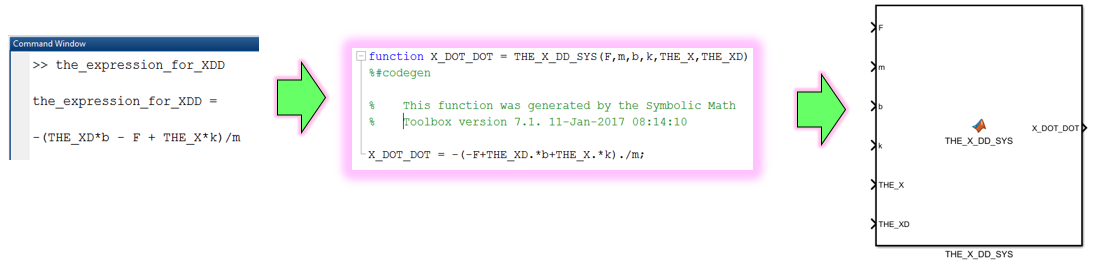

MODEL_NAME        = 'SIM_SMD_WILL_BE_DELETED';
close_system(MODEL_NAME,0); new_system(MODEL_NAME);  open_system(MODEL_NAME)

Automatically convert our $\ddot{x}$ expression into s Simulink block:

matlabFunctionBlock( [MODEL_NAME,'/THE_X_DD_SYS'], the_expression_for_XDD, ...
                         'Vars',     {F, m,b,k,THE_X,THE_XD}, ...
                         'Outputs',  {'X_DOT_DOT'}   ); 

Evaluating callback 'PostLoadFcn' for simulink
Callback: setsysloc_simulink(bdroot)
Evaluating callback 'LoadFcn' for simulink/Sources/Waveform Generator
Callback: set_param(gcb,'LoadFlag','1');


Evaluating callback 'LoadFcn' for simulink/Sources/Signal Builder
Callback: sigbuilder_block('load');
Evaluating callback 'LoadFcn' for simulink/Model-Wide Utilities/Model Info
Callback: slcm LoadBlock;
Evaluating callback 'LoadFcn' for simulink/Sinks/XY Graph
Callback: sfunxy([],[],[],'LoadBlock')
Evaluating callback 'LoadFcn' for simulink/Math Operations/Slider Gain
Callback: sliderGain_cb(gcbh, 'load');


Make the block yellow:

set_param([MODEL_NAME,'/THE_X_DD_SYS'],'BackgroundColor', '[0.996078, 1.000000, 0.705882]');                    

# STEP_6:  Simulate the model of the dynamic system

Let's use the model that we just derived, and implement it in Simulink - where we'll numerically solve it.  Recall our fundamental equation of motion for the spring mass damper system:      $m\ldotp \ddot{x} \text{ }\text{ }+\text{ }\text{ }b\ldotp \dot{x} \text{ }\text{ }+\text{ }\text{ }k\ldotp x=F\left(t\right)$ .  The parameters that we'll use for this Numerical simulation are:

- 
$$m,c,k\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }=1,4,100\text{         }$$
  

- 
$$x\left(0\right)\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }=5$$


- 
$$\dot{x} \left(0\right)\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }=0$$
 

- 
$$F\left(t\right)\text{          }=\text{ }200\ldotp u\left(t-5\right)$$


Have a look at our Simulink model .... and NOTE how we use the integrator blocks to integrate:   $\ddot{x} \to \text{ }\frac{1}{s}\text{ }\to \dot{x} \to \text{ }\frac{1}{s}\to x$

open_system('bh_a_spring_mass_model')  

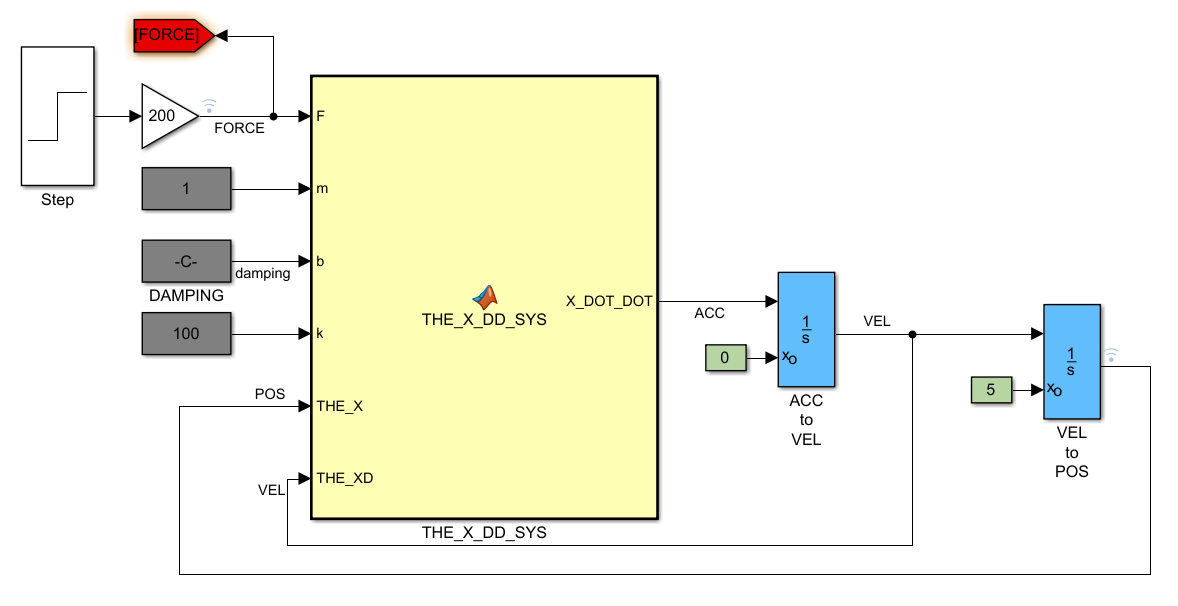

# APPENDIX_A:   Another way of thinking about the isolation of $\ddot{x}$

An alternate approach for arranging our derived equations of motion, is to collect terms into the following buckets:

- 
$$\left\lbrack M\left(q\right)\right\rbrack \;\;,\;\;\;\left\lbrack C\left(q,\dot{q} \right)\right\rbrack \;,\;\;\;\left\lbrack K\left(q\right)\right\rbrack$$


This then allows us to present the system as: 

- 
$$\left\lbrack M\left(q\right)\right\rbrack \ldotp \ddot{q} \;+\;\left\lbrack C\left(q,\dot{q} \right)\right\rbrack \ldotp \dot{q} \;+\;\left\lbrack K\left(q\right)\right\rbrack \ldotp q\;\;\;\;=F\left(q,\dot{q} \right)$$


Which in turn allows us to numerically solve the dynamics by integrating the following:

- $\ddot{q} \;$ = ${\left\lbrack M\left(q\right)\right\rbrack }^{-1} \;\ldotp \;\left\lbrace F\left(q,\dot{q} \right)-\left\lbrack C\left(q,\dot{q} \right)\right\rbrack \ldotp \dot{q} \;-\;\left\lbrack K\left(q\right)\right\rbrack \ldotp q\;\;\right\rbrace \;$

Have a look at an example of how to do this "bucket" (or binning) task:

our_EOM_LHS     =  subs(our_EOM_LHS, actual_list, HOLDER_list);
our_EOM_RHS     =  subs(our_EOM_RHS, actual_list, HOLDER_list);

our_EOM_LHS     = formula(our_EOM_LHS)

$$our\_EOM\_LHS = {\mathrm{THE}}_{X}\,k+{\mathrm{THE}}_{\mathrm{XDD}}\,m$$

our_EOM_RHS     = formula(our_EOM_RHS)

$$our\_EOM\_RHS = F-{\mathrm{THE}}_{\mathrm{XD}}\,b$$

Now do the binning:

[L_tmp_M_mat, L_tmp_C_mat, L_tmp_K_mat, ~]           = LOC_bucket_MCKG(our_EOM_LHS, THE_XDD, THE_XD, THE_X);
[R_tmp_M_mat, R_tmp_C_mat, R_tmp_K_mat, R_tmp_F_mat] = LOC_bucket_MCKG(our_EOM_RHS, THE_XDD, THE_XD, THE_X);

So what have we got ?

tmp_M_mat = L_tmp_M_mat - R_tmp_M_mat

$$tmp\_M\_mat = m$$

tmp_C_mat = L_tmp_C_mat - R_tmp_C_mat

$$tmp\_C\_mat = b$$

tmp_K_mat = L_tmp_K_mat - R_tmp_K_mat

$$tmp\_K\_mat = k$$

tmp_F_mat = R_tmp_F_mat

$$tmp\_F\_mat = F$$

# Local support functions:

Here's an example of a function that groups terms into M,C,K,G for a single DOF system.

-  A more industrial version of this can be found in the file `bh_lagr4manips_CLS.m`

function [M_mat, C_mat, K_mat, G_mat] = LOC_bucket_MCKG(our_EOM_LHS, THE_XDD, THE_XD, THE_X)
        
    M_mat = zeros(1,1,'sym');
    C_mat = zeros(1,1,'sym');
    K_mat = zeros(1,1,'sym'); 
    G_mat = zeros(1,1,'sym');
    
    % convert our equation into a list of terms
    express_list    = children( expand(our_EOM_LHS) );
    
    % we'll process each term in our expression and interrogate that term
    % with the COEFF() function.  Here's how the COEFF() function works:
    %
    % EXAMPLE_#1:
    %     syms x
    %     [C,T] = coeffs(10*x^3, x, 'All')
    %
    %      C = 
    %          [ 10,   0,   0,  0]
    %      T =
    %          [ x^3, x^2,  x,  1]
    %-------------------------------------------
    % EXAMPLE_#2:
    %     [C,T] = coeffs( sin(x^2), x, 'All')
    %  
    %      C =  
    %          sin(x^2)
    %  
    %      T = 
    %          1
    %-------------------------------------------
    %
    % So NOTE the following:
    %   a.) if our TERM(eg: 10*x^3) contains the TARGET symbolic variable(eg: x) in the form
    %       of a POWER of that TARGET symbol, then our C array will contain
    %       more than 1 element.  If the TARGET symbol is NOT present in
    %       the form of a POWER, then C will contain EXACTLY 1 element.
    
    % process each term in the list
    for kk=1:length(express_list)
        the_term = express_list(kk);
        
        % does the term contain ACCELERATION symbols
        tf_has_acc_term = false;
        [C, T]          = coeffs(the_term, THE_XDD, 'All');
        if( length(C)>1 )
            assert( 2==length(C) ); 
            this_M          = C(1); 
            tf_has_acc_term = true;
        end
        
        if(true==tf_has_acc_term)
            M_mat = M_mat + this_M;
            continue
        end
        
        % does the term contain VELOCITY symbols
        tf_has_vel_term = false;
        [C, T]      = coeffs(the_term, THE_XD, 'All');
        % example output:
        %     syms x
        %     [C,T] = coeffs(10*x^3, x, 'All')
        %
        %      C = 
        %          [ 10,   0,   0,  0]
        %      T =
        %          [ x^3, x^2,  x,  1]
        %-------------------------------------------
        %  Np = 3 = numel(C) - 1
        %
        % So what I want to do is:  C(1)*x^2:
        %
        %  C_row = 10*x^2 
        %-------------------------------------------
        
        if( length(C)>1 )
            %assert( 2==length(C) ); 
            n               = length(C); 
            pow_term        = THE_XD^(n-2);
            this_C          = C(1) * pow_term; 
            tf_has_vel_term = true;
        end
    
        if(true==tf_has_vel_term)
           C_mat = C_mat + this_C;
           continue
        end
        
        % does the term contain POSITION symbols
        tf_has_pos_term = false;
        [C, T]          = coeffs(the_term, THE_X, 'All');
            
        % look for linear terms ONLY. Anything NOT linear
        % we'll let it drop through to the G vector
        if( length(C)==2 )
            this_K = C(1); 
            tf_has_pos_term = true;
        end
        
        if(true==tf_has_pos_term)
            K_mat = K_mat + this_K;
            continue
        end
        
        % and if we get to here .... you're in the G_mat
        G_mat = G_mat + the_term;
        
    end % for kk=1:length(express_list)

end % function